load('TrainedOverSampledFijiIDCardClassifier.mat', 'netTransfer');

% Define the path to the image 12686 13540 13566 13551
imagePath = 'C:\IDs\12686.jpg';

% Read the image
img = imread(imagePath);

% Get the input size of the network
inputSize = netTransfer.Layers(1).InputSize;

% Resize the image to match the input size of the network
imgResized = imresize(img, inputSize(1:2));

% Classify the image
[YPred, scores] = classify(netTransfer, imgResized);

% Display the image with the predicted label as the title
disp(['Predicted label: ', char(YPred)]);

Predicted label: Passport


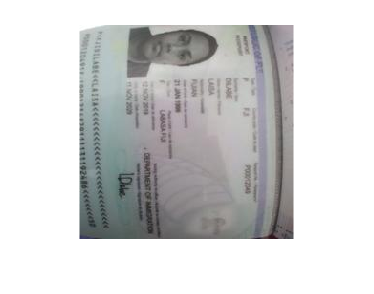

figure;
imshow(img);

% title(['Predicted: ', char(YPred)]);

disp('Class probabilities:');

Class probabilities:


scoresTable = table(netTransfer.Layers(end).Classes, transpose(scores), 'VariableNames', {'Class', 'Probability'});
disp(scoresTable);

          Class          Probability
    _________________    ___________

    DriversLicense       5.1345e-14 
    JointFNPFTIN         1.1721e-11 
    Passport                0.99998 
    VoterRegistration    2.2722e-05 



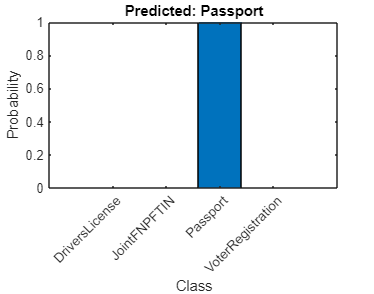


bar(scores);
title(['Predicted: ', char(YPred)]);
xlabel('Class');
ylabel('Probability');
xticklabels(netTransfer.Layers(end).Classes);
xtickangle(45);

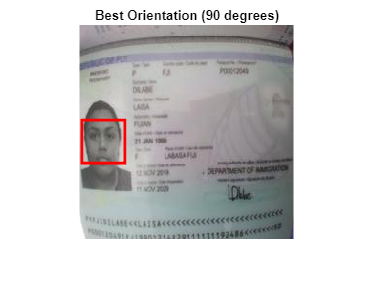


rotations = [0, 90, 180, 270];
maxFaces = 0;
bestOrientation = 0;
bestBboxes = [];
bestImg = img;

% Step 3: Detect Faces in each orientation
for i = 1:length(rotations)
    rotatedImg = imrotate(img, rotations(i));
    faceDetector = vision.CascadeObjectDetector(); % Create a detector object
    bboxes = step(faceDetector, rotatedImg); % Detect faces
    
    % Check if this orientation detects more faces
    numFaces = size(bboxes, 1);
    if numFaces > maxFaces
        maxFaces = numFaces;
        bestOrientation = rotations(i);
        bestBboxes = bboxes;
        bestImg = rotatedImg;
    end
end

% Step 4: Extract Faces from the best orientation
faceImages = cell(maxFaces, 1); % Cell array to hold extracted face images

for i = 1:maxFaces
    % Extract the bounding box for the current face
    x = bestBboxes(i, 1);
    y = bestBboxes(i, 2);
    width = bestBboxes(i, 3);
    height = bestBboxes(i, 4);
    
    % Crop the face from the image
    faceImages{i} = imcrop(bestImg, [x, y, width, height]);
end

% Step 5: Display Results
% Display the best oriented image with bounding boxes
figure;
imshow(bestImg);
hold on;
for i = 1:maxFaces
    rectangle('Position', bestBboxes(i, :), 'EdgeColor', 'r', 'LineWidth', 2);
end
title(['Best Orientation (', num2str(bestOrientation), ' degrees)']);
hold off;

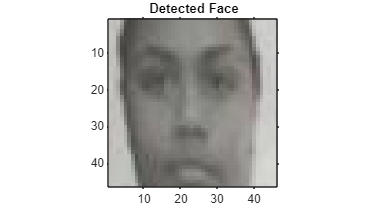


% Display the extracted faces in larger size
figure;
numCols = min(maxFaces, 5); % Number of columns in the subplot grid (up to 5)
numRows = ceil(maxFaces / numCols); % Number of rows in the subplot grid
subplot(numRows, numCols, maxFaces);
    imshow(faceImages{maxFaces}, 'InitialMagnification', 'fit'); % Adjust magnification to fit the subplot
    axis on; % Turn on axis to see the boundaries
    title('Detected Face');
set(gcf, 'Position', get(0, 'Screensize')); % Maximize figure window